# IEEE 123 Node Test Feeder

This script builds the IEEE 123 Node Test Feeder in Simscape Electrical. The model is EMT and contains quasi-static constant PQ and constant current loads. These loads are single-phase, but to avoid a PLL the loads have been implemented as three-phase equivalent, by creating -120 degree and +120 degree phase shifted versions of the single-phase voltage in order to take advantage of Clarke and Park implementation. This implementation, while computationally more expensive, allows clean reference signals within 2/3 of a cycle to be created. This approach is valid for quasi-static EMT simulations with fixed frequency.

Copyright (C) 2026, The MathWorks, Inc.

bdclose all
clear

## load data

IEEE_123_data

## model name

mdl = 'blank_canvas_ssc';

open(mdl)

## add buses

bus_placement_ssc_EMT(mdl,data)

## add lines

line_placement_ssc_EMT(mdl,data)

## add breakers

breaker_placement_ssc(mdl,data)

## add loads

load_placement_ssc_EMT(mdl,data)

## add capacitors

capacitor_placement_ssc(mdl,data)

## add source

source_placement_ssc(mdl,data)

## data saving

define_outputs(mdl)

## set inputs

tagPQ = define_inputs(mdl);

## save to a new model name

new_mdl = 'IEEE_123_EMT';

save_system(mdl,new_mdl);

## define loads

mdl = new_mdl;

define_loads_EMT

Ts = 5e-5;

save param123

## simulate system to compare with benchmark

If previous model build steps have already been performed, you can run this section directly. The plot shows both EMT and RMS values.

load param123

mdl = 'IEEE_123_EMT';

open_system(mdl)

set_param(mdl, 'FastRestart', 'on');

tic;y = sim(mdl,'StopTime','0.2');toc

### Building the Accelerator target for model: IEEE_123_EMT
### Successfully built the Accelerator target for model: IEEE_123_EMT

Build Summary

Top model accelerator targets:

Model         Build Reason                          Status                        Build Duration
IEEE_123_EMT  Accelerator MEX file is out of date.  Code generated and compiled.  0h 2m 16.719s 

1 of 1 models built (0 models already up to date)
Build duration: 0h 2m 17.138s
Elapsed time is 289.378286 seconds.


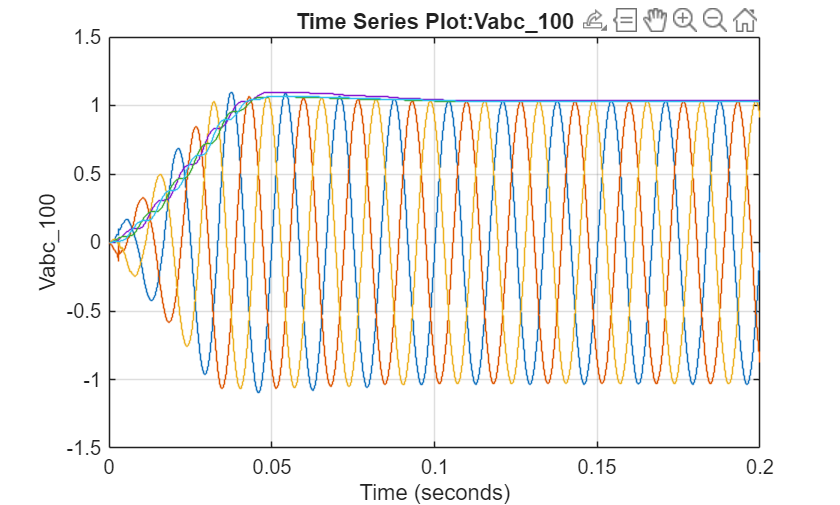


idx = find(ismember(y.logsout.getElementNames,'Vmeas'));

figure(1),plot(y.logsout{idx}.Values.Vabc_100),grid

## compare benchmark results

Bus Voltage

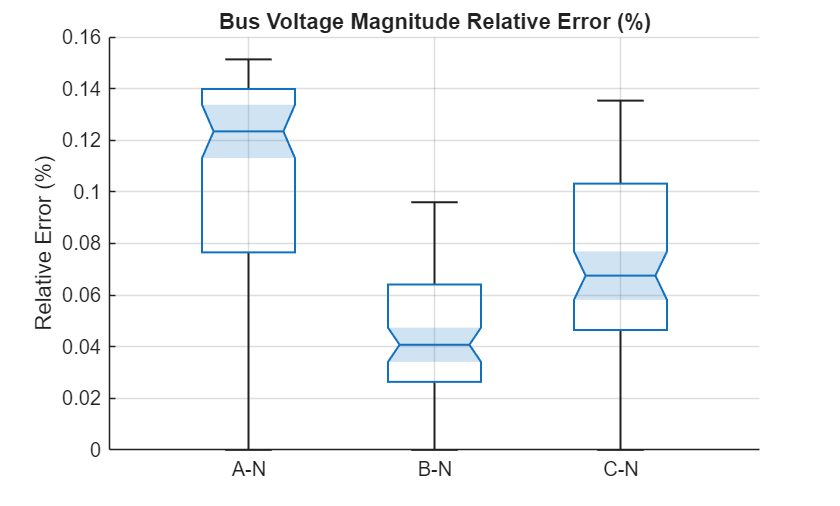

load Vbench_data

VAN = abs(Vbench.VAN);
VBN = abs(Vbench.VBN);
VCN = abs(Vbench.VCN);
Bus_No = Vbench.Bus_No;

v_rel_error_perc = NaN*zeros(numel(Bus_No),3);

fn = fieldnames(y.logsout{idx}.Values);

nt = numel(y.logsout{idx}.Values.Vabc_100.Time);

for x = 1:numel(Bus_No)


    idx1 = find(ismember(fn,['Vabc_',num2str(Bus_No(x))]));
    
    sv = size(y.logsout{idx}.Values.(['Vabc_',num2str(Bus_No(x))]).Data,1);

    if sv == nt
        sv = 2;
    end

    if sv == 6
        vv = reshape(y.logsout{idx}.Values.(['Vabc_',num2str(Bus_No(x))]).Data,6,nt);
    elseif sv == 4
        vv = reshape(y.logsout{idx}.Values.(['Vabc_',num2str(Bus_No(x))]).Data,4,nt);
    else
        vv = reshape(y.logsout{idx}.Values.(['Vabc_',num2str(Bus_No(x))]).Data,2,nt);
    end

    if sv~=2
        vmax = y.logsout{idx}.Values.(['Vabc_',num2str(Bus_No(x))]).Data(:,:,end); %#ok<*UDIM>
    else
        vmax = y.logsout{idx}.Values.(['Vabc_',num2str(Bus_No(x))]).Data(end,:); %#ok<*UDIM>
    end

    vmax = vmax(ceil(numel(vmax)/2)+1:end);

    rel_error_perc = 100*abs(vmax' - rmmissing([VAN(x) VBN(x) VCN(x)]))./rmmissing([VAN(x) VBN(x) VCN(x)]);

  
    idxnn = ~isnan([VAN(x) VBN(x) VCN(x)]);

    v_rel_error_perc(x,idxnn) = rel_error_perc;


end

figure(1),bc = boxchart(v_rel_error_perc);grid
bc.Notch = 'on';
ha = gca;
ha.XTickLabel = {'A-N','B-N','C-N'};
ylabel('Relative Error (%)')
title('Bus Voltage Magnitude Relative Error (%)')

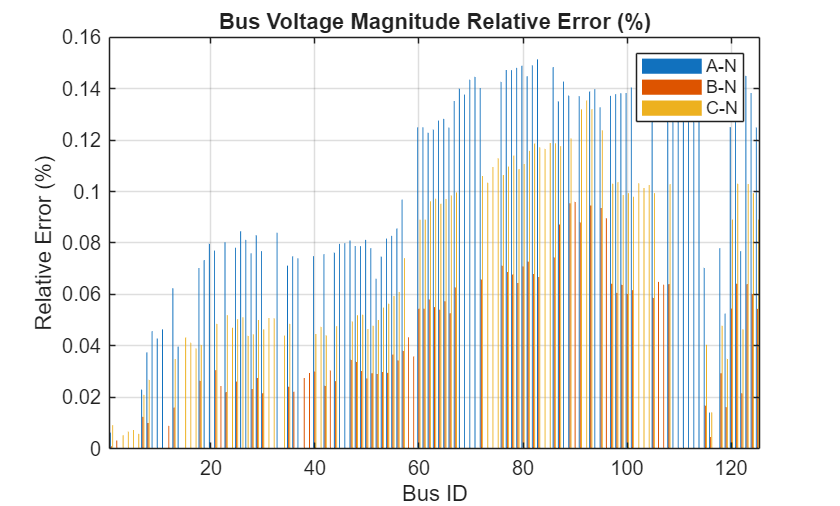


figure(2),bar(v_rel_error_perc),grid
xlabel('Bus ID')
ylabel('Relative Error (%)')
legend('A-N','B-N','C-N')
title('Bus Voltage Magnitude Relative Error (%)')

## Simulate changes to loading conditions

In this section, we step change each constant PQ and constant current load reference values by +50%, and sequence the load changes to be sequential and occurring every 2 cycles. There are 76 loads with time-domain PQ references, 152 reference signals in total. This demonstrates the use of time-domain power reference inputs to change operational condition, as well as demonstrating that the quasi-static load changes settle quickly. The load changes begin at 0.2s and end at 0.2+152*2/60 = 5.27s.

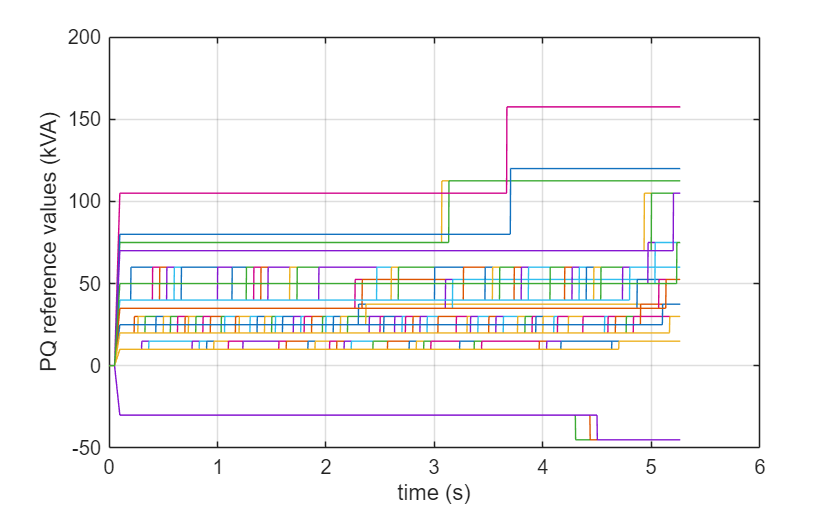

define_loads_EMT

num_cycles = 2;

for x = 1:152

    idxT = t >= 0.2 + num_cycles/60*(x-1);

    load_inputs(idxT,x) = load_inputs(idxT,x)*1.5; %#ok<*SAGROW>

end

tstop = 0.2 + num_cycles/60*152;

idxT = t <= tstop;

figure(3),plot(t(idxT),load_inputs(idxT,:)/1e3),grid
xlabel('time (s)')
ylabel('PQ reference values (kVA)')


tic;y1 = sim(mdl,'StopTime',num2str(tstop));toc

Elapsed time is 127.591682 seconds.


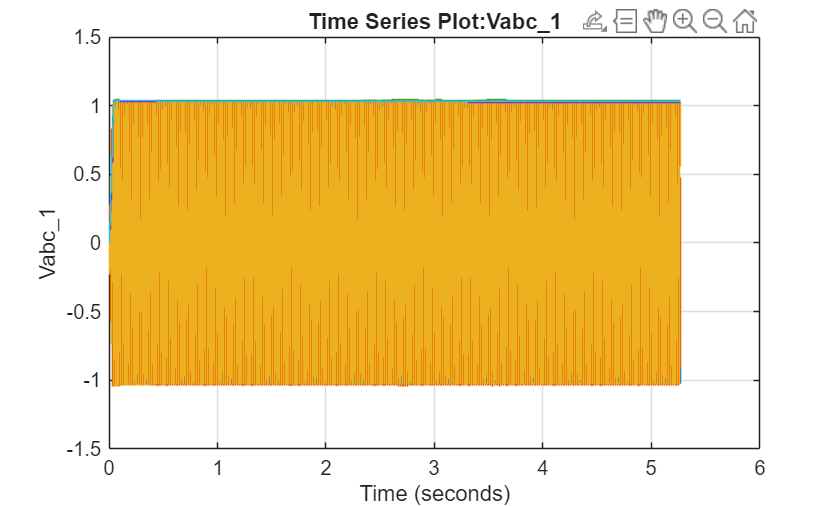


figure(4),plot(y1.logsout{2}.Values.Vabc_1),grid

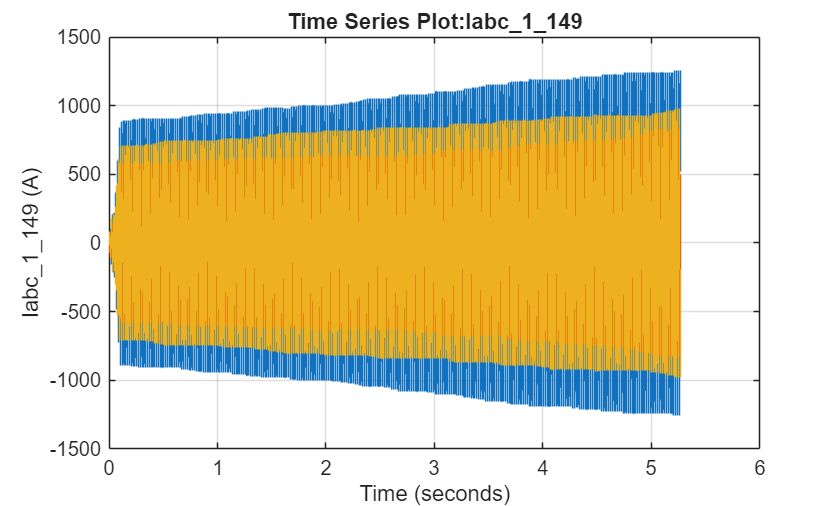

figure(5),plot(y1.logsout{1}.Values.Iabc_1_149),grid